clear;
A = [0 1; 0 0];
B = [0; 1];
Bw = [1 0; -1 0];
x0 = [0; 0];
w0 = [0; 0];
C = [1 0];
Dw = [0 1];

Cz1 = [-1 2; 0 0];
Dz1 = [0; 1];


Cz2 = [0 0; -2 1];
Dz2 = [1; 0];

%=====Checkers=====
a1 = det(Dz1'*Dz1);
a2 = det(Dz2'*Dz2);
a3 = det(Dw*Dw')

a3 = 1

ans_1 = Cz1'*Dz1;
ans_2 = Cz2'*Dz2;
ans_3 = Bw*Dw'

ans_3 =      0
     0


U = [B A*B];
du1 = rank(U);
U2 = [Bw A*Bw]

U2 =      1     0    -1     0
    -1     0     0     0


du2 = rank(U2)

du2 = 2

V = [C; C*A]

V =      1     0
     0     1


dv = rank(V)

dv = 2

V1 = [Cz1; Cz1*A];
dv1 = rank(V1);
V2 = [Cz2; Cz2*A];
dv2 = rank(V2);



C_Z = Cz2;
D_Z = Dz2;

% Вычисляем необходимые компоненты
R = D_Z' * D_Z;
Q_riccati = C_Z' * C_Z;

% Решаем уравнение Риккати
[Q,~,K] = icare(A, B, Q_riccati, R, [], [], [], 1);

% Выводим решение
disp('Решение Q:');

Решение Q:


disp(Q);

    6.4721    2.0000
    2.0000    2.2361




K = -pinv(D_Z' * D_Z)*B'*Q;
disp('Решение K:');

Решение K:


disp(K);

   -2.0000   -2.2361



disp(eig(A+B*K));

  -1.1180 + 0.8660i
  -1.1180 - 0.8660i




% Находим наблюдатель
Qr = Bw*Bw';
Rr = Dw*Dw';
[P1,~,~] = icare(A', C', Qr, Rr, [], [], [], 1);  
P1

P1 =     1.7321    1.0000
    1.0000    2.7321


L = -P1* C' * inv(Rr)

L =    -1.7321
   -1.0000



%=====Передаточная функция====
%syms s;
%W_wzL = simplify([C_Z+D_Z*K -D_Z*K]*inv(s*eye(4) - [A+B*K -B*K; zeros(2) A-L*C])*[Bw;Bw-L*Dw])
%sys = ss([A B*K; -L*C A+B*K+L*C], [Bw; Bw-L*Dw], [C_Z D_Z*K], zeros(2, 2))
%TF = tf(sys)


% Передаточная функция
C_l = [C_Z, D_Z*K];
A_l = [A, B*K; L*C, A+B*K-L*C]

A_l =          0    1.0000         0         0
         0         0   -2.0000   -2.2361
   -1.7321         0    1.7321    1.0000
   -1.0000         0   -1.0000   -2.2361


B_l = [Bw; L*Dw]

B_l =     1.0000         0
   -1.0000         0
         0   -1.7321
         0   -1.0000


I_l = eye(4)

I_l =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


%s = tf('s');
%syms s;
%W_wz2 = simplify(C_l*inv(s*I_l-A_l)*B_l)
%W_simp3 = expand(W_wz2)
%W_simp3 = vpa(W_simp3, 3)

sys = ss([A B*K; -L*C A+B*K+L*C], [Bw; -L*Dw], [C_Z D_Z*K], zeros(2, 2))

sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0      -2  -2.236
   x3   1.732       0  -1.732       1
   x4       1       0      -3  -2.236
 
  B = 
          u1     u2
   x1      1      0
   x2     -1      0
   x3      0  1.732
   x4      0      1
 
  C = 
           x1      x2      x3      x4
   y1       0       0      -2  -2.236
   y2      -2       1       0       0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


TF = tf(sys)

TF =
 
  From input 1 to output...
                -5.7 s^2 + 3.7 s + 2
   1:  ---------------------------------------
       s^4 + 3.968 s^3 + 6.873 s^2 + 5.7 s + 2
 
        -3 s^3 - 9.904 s^2 - 18.38 s + 11.75
   2:  ---------------------------------------
       s^4 + 3.968 s^3 + 6.873 s^2 + 5.7 s + 2
 
  From input 2 to output...
       -5.7 s^3 - 2 s^2 + 1.541e-16 s + 5.405e-17
   1:  ------------------------------------------
        s^4 + 3.968 s^3 + 6.873 s^2 + 5.7 s + 2
 
                -5.7 s^2 + 9.4 s + 4
   2:  ---------------------------------------
       s^4 + 3.968 s^3 + 6.873 s^2 + 5.7 s + 2
 
Continuous-time transfer function.


syms s;
W_matrix = [TF(1,1) TF(1,2); TF(2,1) TF(2,2)]

W_matrix =
 
  From input 1 to output...
                -5.7 s^2 + 3.7 s + 2
   1:  ---------------------------------------
       s^4 + 3.968 s^3 + 6.873 s^2 + 5.7 s + 2
 
        -3 s^3 - 9.904 s^2 - 18.38 s + 11.75
   2:  ---------------------------------------
       s^4 + 3.968 s^3 + 6.873 s^2 + 5.7 s + 2
 
  From input 2 to output...
       -5.7 s^3 - 2 s^2 + 1.541e-16 s + 5.405e-17
   1:  ------------------------------------------
        s^4 + 3.968 s^3 + 6.873 s^2 + 5.7 s + 2
 
                -5.7 s^2 + 9.4 s + 4
   2:  ---------------------------------------
       s^4 + 3.968 s^3 + 6.873 s^2 + 5.7 s + 2
 
Continuous-time transfer function.


TF(1,2)

ans =
 
  -5.7 s^3 - 2 s^2 + 1.541e-16 s + 5.405e-17
  ------------------------------------------
   s^4 + 3.968 s^3 + 6.873 s^2 + 5.7 s + 2
 
Continuous-time transfer function.
Model Properties



H2_norm = norm(W_matrix, 2)

H2_norm = 5.8516

trace(C_Z*P1*C_Z')^0.5

ans = 2.3791

Hinf_norm = norm(W_matrix, inf)

Hinf_norm = 8.1023

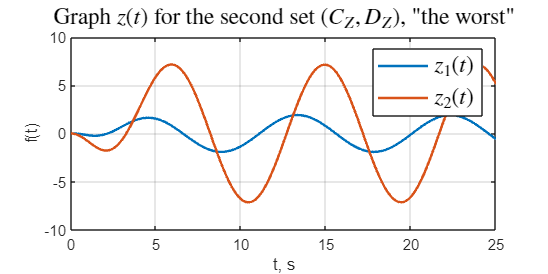


omega = linspace(0, 10, 5000); % От 0.1 до 100 рад/с, 500 точек
%[H, ~] = freqresp(W_matrix, omega_linear);
%{
sigma_values = zeros(2, length(omega)); % Для 2x2 системы (2 сингулярных числа на каждой частоте)
for k = 1:length(omega)
    s = 1i * omega(k); % s = j*omega
    W_freq = evalfr(W_matrix, s); % Вычисление W(j*omega)
    sigma_values(:, k) = svd(W_freq); % Сингулярные числа
end

figure('Position', [100 100 800 400]);
plot(omega, sigma_values(1,:), '-', 'LineWidth',2);
hold on
plot(omega, sigma_values(2,:), ':', 'LineWidth',2);
grid()
title('Graph $\sigma (\omega)$','Interpreter','latex',  'FontSize', 14)
legend('$\sigma_{1}(\omega)$', '$\sigma_{2}(\omega)$', '$A_{21}(\omega)$', '$A_{22}(\omega)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('$\sigma (abs)$', 'Interpreter','latex')
xlabel('$\omega$, rad/s', 'Interpreter','latex')
hold off
%}
%{
figure('Position', [100 100 800 400]);
plot(omega_linear, squeeze(abs(H(1,1,:))), '-', 'LineWidth',2);
hold on
plot(omega_linear, squeeze(abs(H(1,2,:))), '--', 'LineWidth',2);
plot(omega_linear, squeeze(abs(H(2,1,:))), '-.', 'LineWidth',2);
plot(omega_linear, squeeze(abs(H(2,2,:))), ':', 'LineWidth',2);

grid()
title('Graph $A(\omega)$','Interpreter','latex',  'FontSize', 14)
legend('$A_{11}(\omega)$', '$A_{12}(\omega)$', '$A_{21}(\omega)$', '$A_{22}(\omega)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('$|A|$', 'Interpreter','latex')
xlabel('$\omega$, rad/s', 'Interpreter','latex')
hold off
%}
%{
s = tf('s');

%W_wz = simplify((C_Z + D_Z*K)*inv(s*eye(2)-A-B*K)*Bw)
%W_wz = (C_Z + D_Z*K)*inv(s*eye(2)-A-B*K)*Bw;
H2_norm = norm(W_wz, 2)
trace(Bw'*Q*Bw)^0.5
Hinf_norm = norm(W_wz, inf)

w_s = 0:0.001:10;
%ws11 = subs(W_wz(1,1), s, w_s) 

s_1 = sigma(W_wz, w_s);


figure('Position', [100 100 800 400]);
plot(w_s, s_1, '-', 'LineWidth',2);
grid()
title('Graph $\sigma (\omega)$','Interpreter','latex',  'FontSize', 14)
legend('$\sigma_{1}(\omega)$', '$\sigma_{2}(\omega)$', '$A_{21}(\omega)$', '$A_{22}(\omega)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('$\sigma (abs)$', 'Interpreter','latex')
xlabel('$\omega$, rad/s', 'Interpreter','latex')
%}

%{
syms w real;

ww11 = subs(W_wz(1,1), s, 1j*w) 
ww12 = subs(W_wz(1,2), s, 1j*w)
ww21 = subs(W_wz(2,1), s, 1j*w)
ww22 = subs(W_wz(2,2), s, 1j*w)

P1 = [real(ww11) real(ww12); real(ww21) real(ww22)]

Q1 = [imag(ww11) imag(ww12); imag(ww21) imag(ww22)]



Afc1 = simplify(sqrt(P1.*P1 + Q1.*Q1))


w_x = 0:0.001:10;


Afc11 = double(subs(Afc1(1,1), w, w_x));
Afc12 = double(subs(Afc1(1,2), w, w_x));
Afc13 = double(subs(Afc1(2,1), w, w_x));
Afc14 = double(subs(Afc1(2,2), w, w_x));

figure('Position', [100 100 800 400]);
plot(w_x, Afc11, '-', 'LineWidth',2);
hold on
plot(w_x, Afc12, '--', 'LineWidth',2);
plot(w_x, Afc13, '-.', 'LineWidth',2);
plot(w_x, Afc14, ':', 'LineWidth',2);

grid()
title('Graph $A(\omega)$','Interpreter','latex',  'FontSize', 14)
legend('$A_{11}(\omega)$', '$A_{12}(\omega)$', '$A_{21}(\omega)$', '$A_{22}(\omega)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('$|A|$', 'Interpreter','latex')
xlabel('$\omega$, rad/s', 'Interpreter','latex')
hold off
%}


%=====Simulation=========

open_system('task_2_sim');
set_param('task_2_sim/z', 'VariableName', 'z')
out = sim('task_2_sim');

figure('Position', [100 100 800 400])
plot(out.z,'-', 'LineWidth',1.5);

grid()
title('Graph $z(t)$ for the second set $(C_Z, D_Z)$,  "the worst"','Interpreter','latex',  'FontSize', 14)
legend('$z_1(t)$', '$z_2(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
hold off